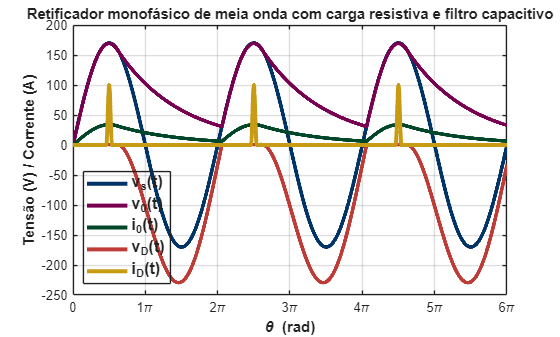

%% Retificador meia-onda + R // C (filtro capacitivo) + corrente no diodo i_D(t)

clear; clc; close all;

f   = 60;
Vm  = 170;
R   = 5;
C   = 1470e-6;
Vd  = 0.7;
ncy = 3;
fs  = 200e3;

T  = 1/f;
dt = 1/fs;
t  = 0:dt:(ncy*T);
N  = numel(t);

v_s = Vm*sin(2*pi*f*t);

v_0  = zeros(1,N);
cond = false(1,N);
for k = 2:N
    if v_s(k) > v_0(k-1) + Vd
        v_0(k)  = v_s(k) - Vd;
        cond(k) = true;
    else
        v_0(k)  = v_0(k-1)*exp(-dt/(R*C));
    end
end

i_0 = v_0 / R;
v_D = v_s - v_0;

dv0_dt = [0 diff(v_0)/dt];
i_C    = C * dv0_dt;

i_D = zeros(1,N);
i_D(cond) = i_0(cond) + i_C(cond);
i_D(i_D<0) = 0;

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;

plotColors = [
    statale.maincolor
    statale.lilla
    statale.darkgreen
    statale.red
    statale.yellow
];
set(groot,'defaultAxesColorOrder',plotColors);

LW = 3.0;
theta = 2*pi*f*t;

Ipk   = 100;
Delta = 0.02*(1/f);

T     = 1/f;
omega = 2*pi*f;

t_peaks = (pi/2 + 2*pi*(0:ceil(ncy)))/omega;
t_peaks = t_peaks(t_peaks >= t(1) & t_peaks <= t(end));

i_D = zeros(size(t));

for kk = 1:numel(t_peaks)
    tau = t - t_peaks(kk);
    m   = abs(tau) <= Delta;

    g = zeros(size(t));
    g(m) = 0.5*(1 + cos(pi*tau(m)/Delta));

    i_D = i_D + Ipk*g;
end

figure('Color','w');
plot(theta, v_s, 'Color', plotColors(1,:), 'LineWidth', LW); hold on;
plot(theta, v_0, 'Color', plotColors(2,:), 'LineWidth', LW);
plot(theta, i_0, 'Color', plotColors(3,:), 'LineWidth', LW);
plot(theta, v_D, 'Color', plotColors(4,:), 'LineWidth', LW);
plot(theta, i_D, 'Color', plotColors(5,:), 'LineWidth', LW);
grid on;

xlabel('\theta (rad)');
ylabel('Tensão (V) / Corrente (A)');
title('Retificador monofásico de meia onda com carga resistiva e filtro capacitivo');

xlim([0, ncy*2*pi]);
xticks(0:pi:(ncy*2*pi));
xticklabels(compose('%g\\pi', (0:1:(ncy*2))));
xticklabels(strrep(xticklabels,'0\pi','0'));

lgd = legend('v_s(t)','v_0(t)','i_0(t)','v_D(t)','i_D(t)','Location','best');
lgd.FontSize   = 12;
lgd.FontWeight = 'bold';
lgd.Color      = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';